# **CONTROLE DISCRETO**

## MÉTODO DA ALOCAÇÃO DE POLOS

# _______________________________________________________________

# 1. Inicialização

## **1.1. VARIÁVEIS E CONSTANTES**

Unidades

precision = 4;
unit = vpasymunit('precision',precision);

Simbologia

s = vpasym('s') / unit.s;  % Frequência complexa s
r = sym('r',  'real');     % Variável de entrada de referência r
warning('off','symbolic:sym:sym:DeprecateExpressions')
REGULADOR    = -1;
SERVO_TIPO_0 =  0;
SERVO_TIPO_1 =  1;

## **1.2. MODELO DO SERVOMECANISMO**

Parâmetros da planta

K   = 1.53   * unit.rad/(unit.V*unit.s)  % Ganho DC

$$K = 1.53\,\frac{\mathrm{rad}}{V\,s}$$

tau = 0.0254 * unit.s                    % Constante de tempo

$$tau = 0.0254\,s$$

Ts  = 0.001  * unit.s                    % Tempo de amostragem

$$Ts = 0.001\,s$$

Planta modelo simbólica contínua

G = K/(s*(tau*s+1))

$$G = \frac{1.53}{s\,\left(0.0254\,s+1.0\right)}\,\frac{\mathrm{rad}}{V}$$

## **1.3. ESPECIFICAÇÕES DE PROJETO**

Parâmetros desejados

goal.ess = 0;              % Erro de estado estacionário
goal.tp  = 0.20 * unit.s;  % Tempo máximo de pico
goal.Mp  = 5.0/100;        % Máximo sobressinal
dispsym('e_ss',goal.ess,precision)

$$e_{\mathrm{ss}}=0.0$$

dispsym('t_p', goal.tp, precision)

$$t_{p}=0.2$$

dispsym('M_p', goal.Mp, precision)

$$M_{p}=0.05$$

# _______________________________________________________________

# 2. Análise preliminar

## **2.1. FUNCÕES DE TRANSFERÊNCIA**

*2.1.1. PLANO CONTÍNUO*

Converte a função de transferência simbólica contínua para numérica contínua

Gs = sym2tf(G)


Gs =
 
      60.24
  -------------
  s^2 + 39.37 s
 
Continuous-time transfer function.



*2.1.2. PLANO DISCRETO*

Converte a função de transferência contínua para a pulsada

Gz = c2d(Gs,val(Ts)) % ou ...


Gz =
 
  2.973e-05 z + 2.934e-05
  -----------------------
  z^2 - 1.961 z + 0.9614
 
Sample time: 0.001 seconds
Discrete-time transfer function.



Gz = zpk(Gz)         % na forma de zeros, polos e ganho


Gz =
 
  2.9727e-05 (z+0.987)
  --------------------
    (z-1) (z-0.9614)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.



## **2.2. ESPAÇO DE ESTADOS**

Ordem do sistema

n = order(Gs)

n = 2

Variáveis de estado

x  = sym('x',[1 n],  'real').'   % Normal    (sem integrador)

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

xi = sym('x',[1 n+1],'real').'   % Expandida (com integrador)

$$xi = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)$$

*2.2.1. PLANO CONTÍNUO*

Converte a função de transferência contínua para o espaço de estados contínuo na forma canônica controlável

[A,B,C,D] = tf2ss2(Gs);
sys = ss(A,B,C,D);
sseqdisp('t',A,'A',B,'B',C,'C',D,'D','u',precision)

$$\frac{\partial }{\partial t}x\left(t\right)=A\,x\left(t\right)+B\,u\left(t\right)$$

$$y\left(t\right)=C\,x\left(t\right)$$

$$A=\left(\begin{array}{cc} 0 & 1.0\\ 0 & -39.37 \end{array}\right)$$

$$B=\left(\begin{array}{c} 0\\ 1.0 \end{array}\right)$$

$$C=\left(\begin{array}{cc} 60.24 & 0 \end{array}\right)$$

Um resultado equivalente pode ser obtido pelos comandos do MATLAB abaixo, onde as variáveis de estado são definidas de forma inversa

[b,a] = tfdata(Gs);
[A_eq,B_eq,C_eq,D_eq] = tf2ss(b{:},a{:});
sys_eq = ss(A_eq,B_eq,C_eq,D_eq);
sseqdisp('t',A_eq,'A_eq',B_eq,'B_eq',C_eq,'C_eq',D_eq,'D_eq','u',precision)

$$\frac{\partial }{\partial t}x\left(t\right)=A_{\mathrm{eq}}\,x\left(t\right)+B_{\mathrm{eq}}\,u\left(t\right)$$

$$y\left(t\right)=C_{\mathrm{eq}}\,x\left(t\right)$$

$$A_{\mathrm{eq}}=\left(\begin{array}{cc} -39.37 & 0\\ 1.0 & 0 \end{array}\right)$$

$$B_{\mathrm{eq}}=\left(\begin{array}{c} 1.0\\ 0 \end{array}\right)$$

$$C_{\mathrm{eq}}=\left(\begin{array}{cc} 0 & 60.24 \end{array}\right)$$

*2.2.2. PLANO DISCRETO*

Converte a função de transferência pulsada para o espaço de estados discreto na forma canônica controlável

[Ad,Bd,Cd,Dd] = tf2ss2(Gz);
sysd = ss(Ad,Bd,Cd,Dd,val(Ts));
sseqdisp('k',Ad,'A_d',Bd,'B_d',Cd,'C_d',Dd,'D_d','u',precision)

$$x\left(k+1\right)=A_{d}\,x\left(k\right)+B_{d}\,u\left(k\right)$$

$$y\left(k+1\right)=C_{d}\,x\left(k\right)$$

$$A_{d}=\left(\begin{array}{cc} 0 & 1.0\\ -0.9614 & 1.961 \end{array}\right)$$

$$B_{d}=\left(\begin{array}{c} 0\\ 1.0 \end{array}\right)$$

$$C_{d}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

Um resultado equivalente pode ser obtido pelos comandos do MATLAB abaixo, onde as variáveis de estado são definidas de forma inversa

[bd,ad] = tfdata(Gz);
[Ad_eq,Bd_eq,Cd_eq,Dd_eq] = tf2ss(bd{:},ad{:});
sysd_eq = ss(Ad_eq,Bd_eq,Cd_eq,Dd_eq,val(Ts));
sseqdisp('k',Ad_eq,'A_deq',Bd_eq,'B_deq',Cd_eq,'C_deq',Dd_eq,'D_deq','u',precision)

$$x\left(k+1\right)=A_{\mathrm{deq}}\,x\left(k\right)+B_{\mathrm{deq}}\,u\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{deq}}\,x\left(k\right)$$

$$A_{\mathrm{deq}}=\left(\begin{array}{cc} 1.961 & -0.9614\\ 1.0 & 0 \end{array}\right)$$

$$B_{\mathrm{deq}}=\left(\begin{array}{c} 1.0\\ 0 \end{array}\right)$$

$$C_{\mathrm{deq}}=\left(\begin{array}{cc} 2.973\,10^{-5} & 2.934\,10^{-5} \end{array}\right)$$

Aumenta o espaço de estados adicionando uma variável integradora do erro

[Adi,Bdi,Cdi,Ddi] = incss(Ad,Bd,Cd,Dd);
sysdi = ss(Adi,Bdi,Cdi,Ddi,val(Ts));
sseqdisp('k',Adi,'A_di',Bdi,'B_di',Cdi,'C_di',Ddi,'D_di','u',precision)

$$x\left(k+1\right)=A_{\mathrm{di}}\,x\left(k\right)+B_{\mathrm{di}}\,u\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{di}}\,x\left(k\right)$$

$$A_{\mathrm{di}}=\left(\begin{array}{ccc} 0 & 1.0 & 0\\ -0.9614 & 1.961 & 0\\ -2.934\,10^{-5} & -2.973\,10^{-5} & 1.0 \end{array}\right)$$

$$B_{\mathrm{di}}=\left(\begin{array}{c} 0\\ 1.0\\ 0 \end{array}\right)$$

$$C_{\mathrm{di}}=\left(\begin{array}{ccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 \end{array}\right)$$

## 2.3. CONTROLABILIDADE

*2.3.1. PLANO CONTÍNUO*

Calcula a matriz de controlabilidade de Kalman contínua

Co = ctrb2(A,B)

Co =          0    1.0000
    1.0000  -39.3701


O mesmo resultado pode ser obtido pelo comando do MATLAB

Co = ctrb(A,B)

Co =          0    1.0000
    1.0000  -39.3701


Verifica se o sistema contínuo é controlável

assert(isctrb(Co),'O sistema contínuo não é completamente controlável')

*2.3.2. PLANO DISCRETO*

Calcula a matriz de controlabilidade de Kalman discreta para a planta sem e com o integrador

Cod  = ctrb2(Ad, Bd )

Cod =          0    1.0000
    1.0000    1.9614


Codi = ctrb2(Adi,Bdi)

Codi =          0    1.0000    1.9614
    1.0000    1.9614    2.8857
         0   -0.0000   -0.0001


Os mesmos resultados podem ser obtidos pelo comando do MATLAB

Cod  = ctrb(Ad, Bd )

Cod =          0    1.0000
    1.0000    1.9614


Codi = ctrb(Adi,Bdi)

Codi =          0    1.0000    1.9614
    1.0000    1.9614    2.8857
         0   -0.0000   -0.0001


Verifica se os sistemas discretos são controláveis (quando sem o integrador, o resultado deve ser o mesmo do contínuo)

assert(isctrb(Cod), 'O sistema discreto não é completamente controlável')
assert(isctrb(Codi),'O sistema discreto com integrador não é completamente controlável')

## **2.4. RESPOSTA DESEJADA**

*2.4.1. PLANO CONTÍNUO*

Coeficiente de amortecimento e frequência natural não amortecida para o tempo de pico e máximo sobressinal desejados em uma resposta de segunda ordem

[goal.zeta, goal.wn] = secordparam(goal.tp,goal.Mp,precision);
dispsym('zeta',   goal.zeta,precision)

$$\zeta =0.6901$$

dispsym('omega_n',goal.wn,  precision)

$$\omega_{n}=21.7$$

Coeficientes e polos do polinômio característico para a solução p = σ ± jωd

[goal.pc, goal.p, goal.sigma, goal.wd] = secord2poles(goal.zeta,goal.wn);
dispsym('pc',     goal.pc,   precision)

$$\mathrm{pc}=\left(\begin{array}{ccc} 1.0 & 29.96 & 471.1 \end{array}\right)$$

dispsym('p',      goal.p',   precision)

$$p=\left(\begin{array}{c} -14.98-15.71\,\mathrm{i}\\ -14.98+15.71\,\mathrm{i} \end{array}\right)$$

dispsym('sigma',  goal.sigma,precision)

$$\sigma =14.98$$

dispsym('omega_d',goal.wd,   precision)

$$\omega_{d}=15.71$$

*2.4.2. PLANO DISCRETO*

Transformação dos polos desejados no plano contínuo para o plano discreto sem integrador

[goal.zpc, goal.zp] = c2dpoles(goal.p,Ts);
dispsym('z_pc',goal.zpc,precision)

$$z_{\mathrm{pc}}=\left(\begin{array}{ccc} 1.0 & -1.97 & 0.9705 \end{array}\right)$$

dispsym('z_p', goal.zp',precision)

$$z_{p}=\left(\begin{array}{c} 0.985-0.01547\,\mathrm{i}\\ 0.985+0.01547\,\mathrm{i} \end{array}\right)$$

Adição de um polo recessivo para o plano discreto com integrador

Krc = 10;                                     % Fator de recessão do polo adicional
[~,zprc]  = c2dpoles(Krc*real(goal.p(1)),Ts)  % Polo recessivo

zprc = 0.8609

goal.zpi  = [goal.zp, zprc];                  % Completa os polos
goal.zpci = poly(goal.zpi);
dispsym('z_pci',goal.zpci,precision)

$$z_{\mathrm{pci}}=\left(\begin{array}{cccc} 1.0 & -2.831 & 2.666 & -0.8355 \end{array}\right)$$

dispsym('z_pi', goal.zpi',precision)

$$z_{\pi }=\left(\begin{array}{c} 0.985-0.01547\,\mathrm{i}\\ 0.985+0.01547\,\mathrm{i}\\ 0.8609 \end{array}\right)$$

Polos na origem para o controlador deadbeat

goal.zpb  = zeros(length(goal.zp),1);
goal.zpcb = poly(goal.zpb);
dispsym('z_pcb',goal.zpcb,precision)

$$z_{\mathrm{pcb}}=\left(\begin{array}{ccc} 1.0 & 0 & 0 \end{array}\right)$$

dispsym('z_pb', goal.zpb',precision)

$$z_{\mathrm{pb}}=\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

# _______________________________________________________________

# 3. Controladores por realimentação de estados

## 3.1. GANHOS DE REALIMENTAÇÃO

*3.1.1. REGULADOR*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Kr = acker2(Ad,Bd,goal.zp)

Kr =     0.0091   -0.0086


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Kr = acker(Ad,Bd,goal.zp)  % ... ou

Kr =     0.0091   -0.0086


Kr = place(Ad,Bd,goal.zp)  % para o caso de um controle robusto

Kr =     0.0091   -0.0086


*3.1.2. SERVOSSISTEMA DO TIPO 1*

Vetor de ganhos é o mesmo de um regulador

Kc = Kr

Kc =     0.0091   -0.0086


*3.1.3. SERVOSSISTEMA COM INTEGRADOR*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Ki = acker2(Adi,Bdi,goal.zpi)

Ki =    -0.1259    0.1305   -1.0930


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Ki = acker(Adi,Bdi,goal.zpi)  % ... ou

Ki =    -0.1259    0.1305   -1.0930


Ki = place(Adi,Bdi,goal.zpi)  % para o caso de um controle robusto

Ki =    -0.1259    0.1305   -1.0930


*3.1.4. DEADBEAT*

Determina o vetor de ganhos da realimentação de estados pela Fórmula de Ackermann

Kb = acker2(Ad,Bd,goal.zpb)

Kb =    -0.9614    1.9614


O mesmo resultado pode ser obtido pelos comandos do MATLAB

Kb = acker(Ad,Bd,goal.zpb)

Kb =    -0.9614    1.9614


## 3.2. ESPAÇO DE ESTADOS COM CONTROLADOR

*3.2.1. REGULADOR*

Matrizes do sistema discreto com o regulador

[Adr,Bdr,Cdr,Ddr,Kffr] = redss(Ad,Bd,Cd,Dd,Kr,REGULADOR);
sysd_regl = ss(Adr,Bdr,Cdr,Ddr,val(Ts));
sseqdisp('k',Adr,'A_dr',Bdr,'B_dr',Cdr,'C_dr',Ddr,'D_dr','u',precision)

$$x\left(k+1\right)=A_{\mathrm{dr}}\,x\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dr}}\,x\left(k\right)$$

$$A_{\mathrm{dr}}=\left(\begin{array}{cc} 0 & 1.0\\ -0.9705 & 1.97 \end{array}\right)$$

$$C_{\mathrm{dr}}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

A solução do regulador é dada por

ur = -Kr*x + Kffr*r;
ur = vpa(ur,precision)

$$ur = 0.008628\,x_{2}-0.009092\,x_{1}$$

*3.2.2. SERVOSSISTEMA DO TIPO 1*

Matrizes do sistema discreto com o servossistema do tipo 1

[Adc,Bdc,Cdc,Ddc,Kffc] = redss(Ad,Bd,Cd,Dd,Kc,SERVO_TIPO_1);
sysd_ctrl = ss(Adc,Bdc,Cdc,Ddc,val(Ts));
sseqdisp('k',Adc,'A_dc',Bdc,'B_dc',Cdc,'C_dc',Ddc,'D_dc','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dc}}\,x\left(k\right)+B_{\mathrm{dc}}\,r\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dc}}\,x\left(k\right)$$

$$A_{\mathrm{dc}}=\left(\begin{array}{cc} 0 & 1.0\\ -0.9705 & 1.97 \end{array}\right)$$

$$B_{\mathrm{dc}}=\left(\begin{array}{c} 0\\ 7.857 \end{array}\right)$$

$$C_{\mathrm{dc}}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

A solução do servossistema do tipo 1 é dada por

uc = -Kc*x + Kffc*r;
uc = vpa(uc,precision)

$$uc = 7.857\,r-0.009092\,x_{1}+0.008628\,x_{2}$$

*3.2.3. SERVOSSISTEMA COM INTEGRADOR*

Matrizes do sistema discreto com o servossistema com integrador

[Adic,Bdic,Cdic,Ddic,Kffic] = redss(Adi,Bdi,Cdi,Ddi,Ki,SERVO_TIPO_0);
sysdi_ctrl = ss(Adic,Bdic,Cdic,Ddic,val(Ts));
sseqdisp('k',Adic,'A_dic',Bdic,'B_dic',Cdic,'C_dic',Ddic,'D_dic','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dic}}\,x\left(k\right)+B_{\mathrm{dic}}\,r\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dic}}\,x\left(k\right)$$

$$A_{\mathrm{dic}}=\left(\begin{array}{ccc} 0 & 1.0 & 0\\ -0.8355 & 1.831 & 1.093\\ -2.934\,10^{-5} & -2.973\,10^{-5} & 1.0 \end{array}\right)$$

$$B_{\mathrm{dic}}=\left(\begin{array}{c} 0\\ 0\\ 1.0 \end{array}\right)$$

$$C_{\mathrm{dic}}=\left(\begin{array}{ccc} 2.934\,10^{-5} & 2.973\,10^{-5} & 0 \end{array}\right)$$

A solução do servossistema do tipo 1 é dada por

uic = -Ki*xi + Kffic*r;
uic = vpa(uic,precision)

$$uic = r+0.1259\,x_{1}-0.1305\,x_{2}+1.093\,x_{3}$$

*3.2.4. DEADBEAT*

Matrizes do sistema discreto com o controlador deadbeat

[Adbc,Bdbc,Cdbc,Ddbc,Kffbc] = redss(Ad,Bd,Cd,Dd,Kb,REGULADOR);
sysdb_ctrl = ss(Adbc,Bdbc,Cdbc,Ddbc,val(Ts));
sseqdisp('k',Adbc,'A_dbc',Bdbc,'B_dbc',Cdbc,'C_dbc',Ddbc,'D_dbc','r',precision)

$$x\left(k+1\right)=A_{\mathrm{dbc}}\,x\left(k\right)$$

$$y\left(k+1\right)=C_{\mathrm{dbc}}\,x\left(k\right)$$

$$A_{\mathrm{dbc}}=\left(\begin{array}{cc} 0 & 1.0\\ 0 & 0 \end{array}\right)$$

$$C_{\mathrm{dbc}}=\left(\begin{array}{cc} 2.934\,10^{-5} & 2.973\,10^{-5} \end{array}\right)$$

A solução do deadbeat é dada por

ubc = -Kb*x + Kffbc*r;
ubc = vpa(ubc,precision)

$$ubc = 0.9614\,x_{1}-1.961\,x_{2}$$

## 3.3. RESPOSTAS SEM E COM CONTROLADOR

Amplitude do sinal de entrada

R = pi/8  % Degrau unitário

R = 0.3927

Tempo final da simulação

tfinal = 1/0.4 * unit.s

$$tfinal = 2.5\,s$$

Estado inicial

x0 = R*ones(n,1)/sysd.C(1)/2;

Analiza as respostas do sistema sem controlador

[X,h] = resposta(sysd,x0,tfinal);

xmin = 6.6924e+03

xmax = 6.6924e+03

xdif = 4.8100e-08

yl =    1.0e+03 *

    6.6924    6.6924


xdif = 6.6924e+03

yl =    1.0e+03 *

   -0.3346    7.0270


xmin = 6.6924e+03

xmax = 6.6924e+03

xdif = 4.8120e-08

yl =    1.0e+03 *

    6.6924    6.6924


xdif = 6.6924e+03

yl =    1.0e+03 *

   -0.3346    7.0270


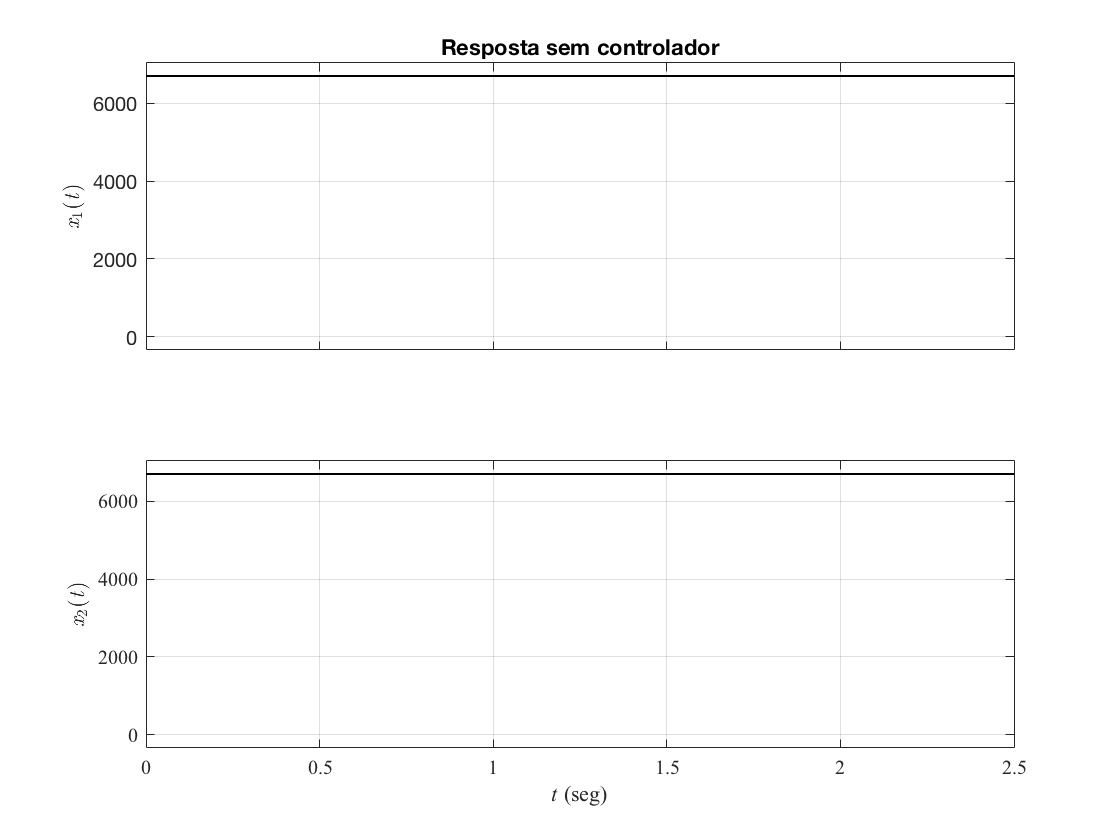

title(h.Children(end),'Resposta sem controlador')

*3.3.1. REGULADOR*

Estado inicial

x0r = R*ones(n,1)/sysd_regl.C(1)/2;

Analiza as respostas do sistema com regulador

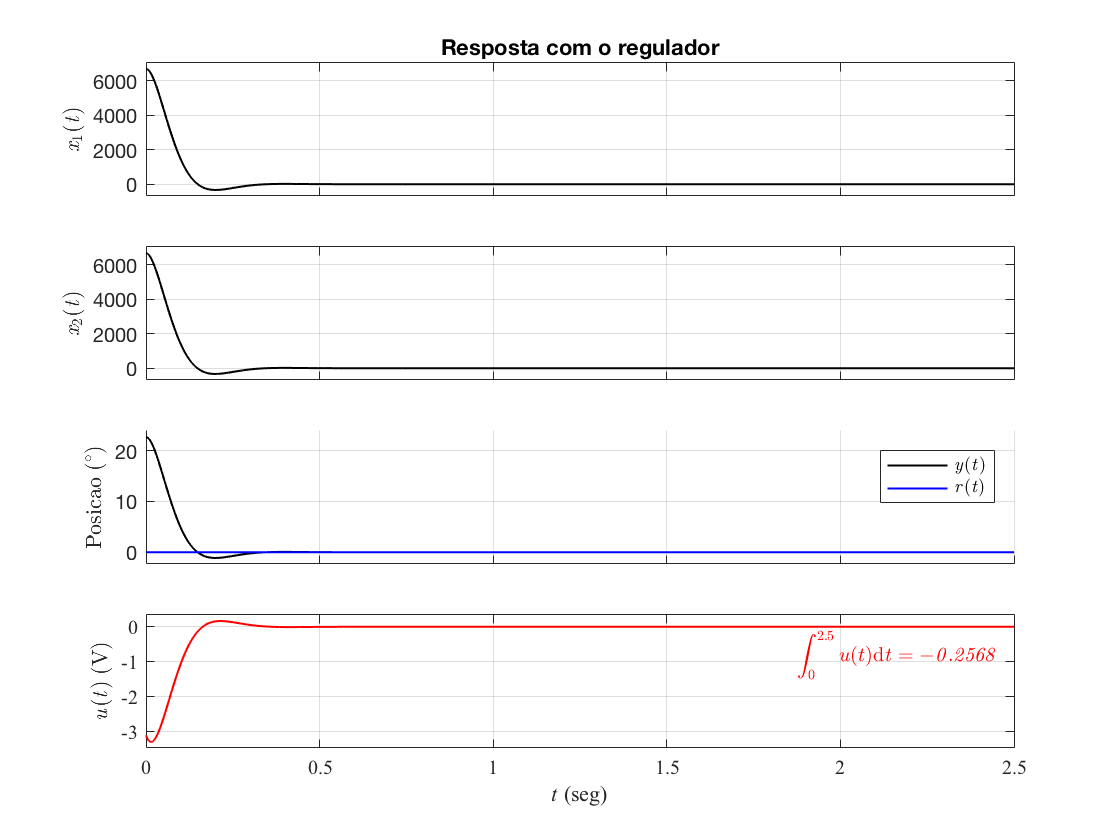

[Xr,Yr,Ur,hr] = resposta(sysd_regl,x0r,tfinal,ur);
title(hr.Children(end),'Resposta com o regulador')

*3.3.2. SERVOSSISTEMA DO TIPO 1*

Estado inicial

x0c = zeros(n,1);

Analiza as respostas do sistema com servossistema do tipo 1

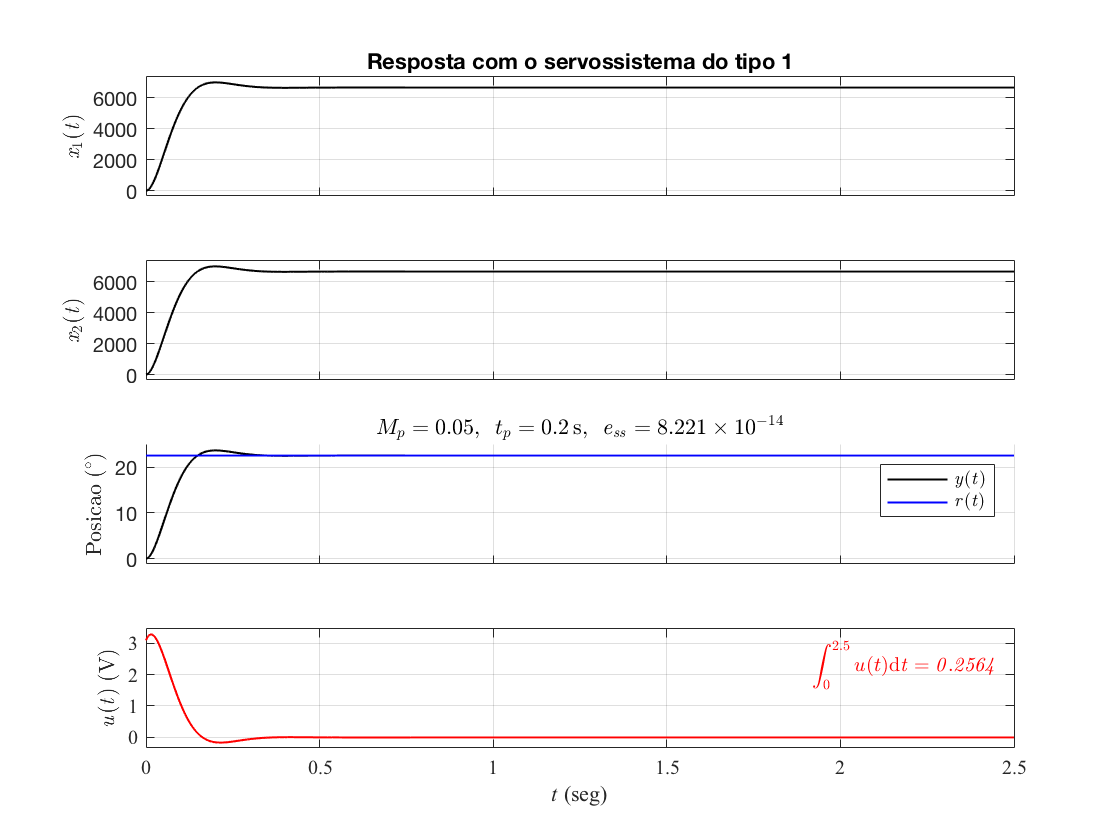

[Xc,Yc,Uc,Rc,hc] = resposta(sysd_ctrl,x0c,tfinal,uc,R);
title(hc.Children(end),'Resposta com o servossistema do tipo 1')

*3.3.3. SERVOSSISTEMA COM INTEGRADOR*

Estado inicial

x0i = zeros(n,1);

Analiza as respostas do sistema com servossistema com integrador

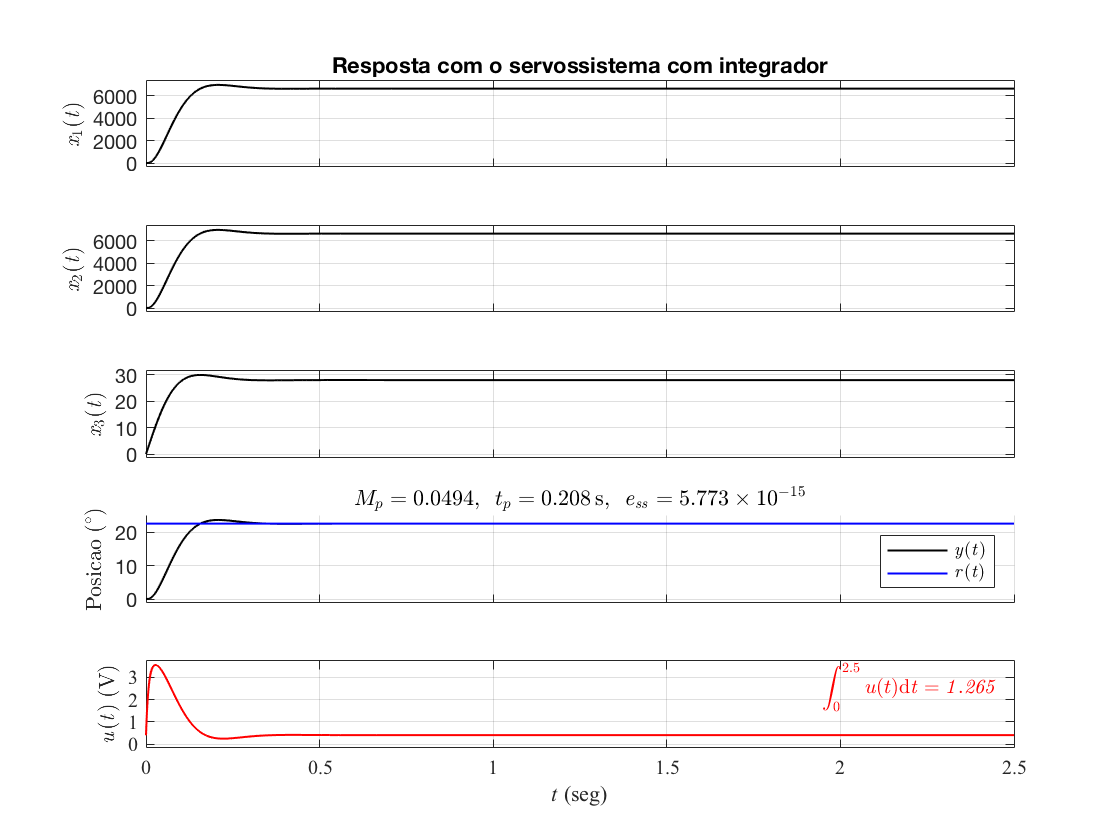

[Xic,Yic,Uic,Ric,hic] = resposta(sysdi_ctrl,x0i,tfinal,uic,R);
title(hic.Children(end),'Resposta com o servossistema com integrador')

*3.3.4. DEADBEAT*

Estado inicial

x0b = R*ones(n,1)/sysdb_ctrl.C(1)/2;

Analiza as respostas do sistema com controlador deadbeat

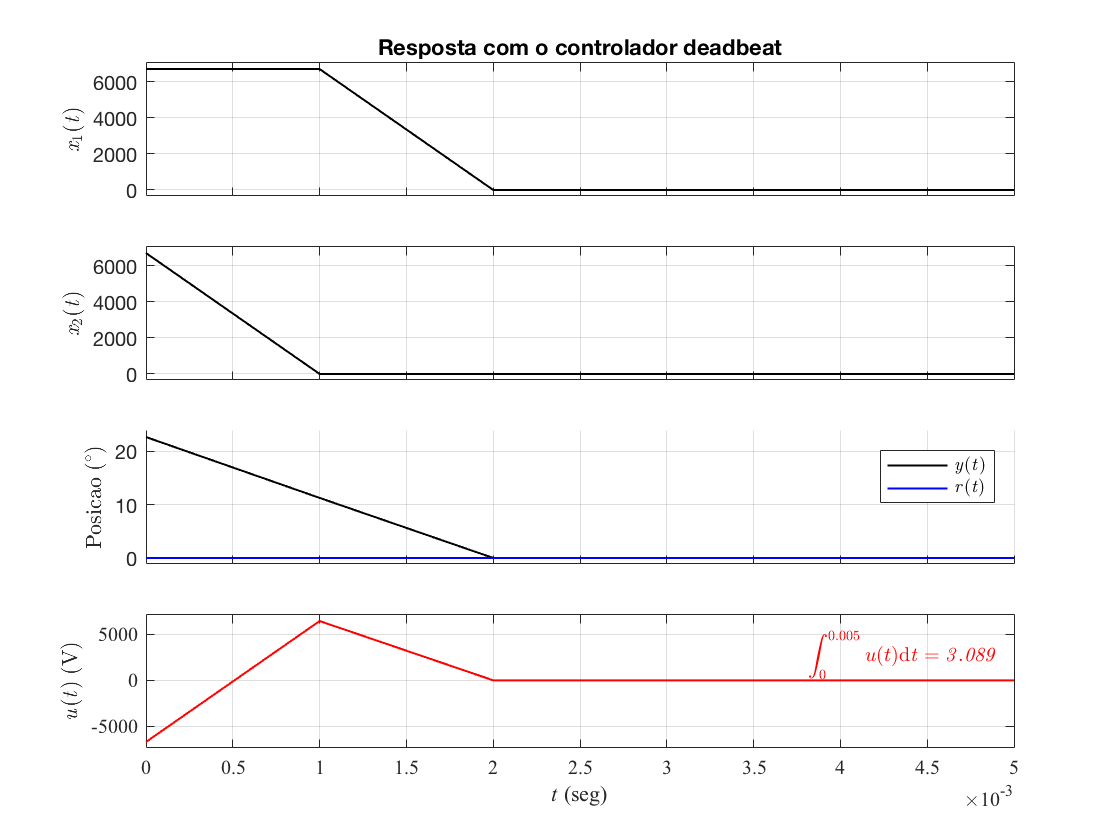

[Xbc,Ybc,Ubc,hbc] = resposta(sysdb_ctrl,x0b,5*Ts,ubc);
title(hbc.Children(end),'Resposta com o controlador deadbeat')

# _______________________________________________________________

# FUNÇÕES INTERNAS

## VAL

Retorna o valor de uma variável simbólica com unidade

*Sintaxe:*   y` = val(x)`

*Entrada:  x*  Variável simbólica com unidade

*Saída:*     *y*  Valor `double` da variável simbólica

function y = val(x)
    y = double(separateUnits(x));
end

## UNITS

Retorna as unidades de uma variável simbólica com unidade

*Sintaxe:*   u` = units(x)`

*Entrada:  x*  Variável simbólica com unidade

*Saída:*     *u*  Unidades `string` da variável simbólica

function u = units(x)
    u = char(x);
    u = replace(u,'symunit','');
    u = replace(u,'(','');
    u = replace(u,')','');
    u = replace(u,'''','');
end

## DISPSYM

Exibe uma variável simbólica de nome `name` igual a um valor `x`

*Sintaxe:*   `dispsym(name,x,precision)`

*Entrada:  *`name        `Nome da variável simbólica a ser exibido

                `x`           Valor da variável simbólica a ser exibido

                `precision`   Valor da precisão numérica utilizada na exibição

function dispsym(name,x,precision)
    disp(vpa(sym([name ' == ' char(sym(val(x)))]),precision))
end

## SYM2TF

Converte uma Função de Transferência Simbólica para uma Função de Transferência Numérica

*Sintaxe:*    `G = sym2tf(g)`

*Entrada:   *`g`  Função de Transferência Simbólica

*Saída:*      `G`  Função de Transferência Numérica

function G = sym2tf(g)
    g = separateUnits(g);
    [n,m] = size(g);
    G = tf(zeros(n,m));
    for i = 1:n
        for j = 1:m
            [num,den] = numden(g(i,j));
            num_n = sym2poly(num);
            den_n = sym2poly(den);
            num_n = num_n/den_n(1);
            den_n = den_n/den_n(1);
            G(i,j) = tf(num_n,den_n);
        end
    end
%     G = zpk(G);
end

## TF2SYM

Converte uma Função de Transferência Numérica para uma Função de Transferência Simbólica Numérica

*Sintaxe:*   `g = tf2sym(G,var)`

*Entrada:  *`G`  Função de Transferência Numérica

                `var`  (*opcional*) Variável simbólica da frequência complexa

*Saída:*      `g`  Função de Transferência Simbólica

function g = tf2sym(G,var,precision)
    if nargin < 2
        var = vpasym('s');
    elseif ischar(var)
        var = vpasym(var);
    end
    if nargin < 3
        precision = [];
    end
    [n,m] = size(G);
    g = vpasym(zeros(n,m));
    for i = 1:n
        for j = 1:m
            [z,p,k] = zpkdata(G(i,j));
            z = z{:};
            p = p{:};
            num = 1;
            for r = 1:length(z)
                num = num * (var - z(r));
            end
            den = 1;
            for r = 1:length(p)
                den = den * (var - p(r));
            end
            f = collect(k*num/den,k);
            g(i,j) = vpasym(f,'precision',precision);
        end
    end
end

## TF2SS2

Retorna as matrizes `A`, `B`, `C` e `D` na forma canônica controlável do espaço de estados da função de transferência com numerador e denominador de coeficientes respetivos `b` e `a`, ou de expressão simbólica `g` ou de expressão numérica `sys`

*Sintaxe:*    `[A,B,C,D] = tf2ss2(b,a)`

`        [A,B,C,D] = tf2ss2(g)`

`        [A,B,C,D] = tf2ss2(sys)`

*Entrada:    *`b   `Numerador da função de transferência

`        a   `Denominador da função de transferência

`        g   `Função de Transferência Simbólica

`        sys `Função de Transferência Numérica

*Saída:       *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

`        C   `Matriz de saída

`        D   `Matriz de transição direta

function [A,B,C,D] = tf2ss2(varargin)
    if nargin == 1
        sys = varargin{1};
        try
            [b,a] = tfdata(sys);
            b = b{:};
            a = a{:};
        catch ME
            if isa(sys,'sym')
                [b,a] = numden(sys);
                b = coeffs(b,'All');
                a = coeffs(a,'All');
            else
                throw(ME)
            end
        end
    else % nargin == 2
        b = varargin{1};
        a = varargin{2};
    end
    n = length(a)-1;                % Ordem do sistema
    b = fliplr(b);                  % Inverte a contagem dos coeficientes
    a = fliplr(a);                  % Inverte a contagem dos coeficientes
    b = b/a(n+1);                   % Força a(n+1) = 1
    a = a/a(n+1);                   % Força a(n+1) = 1
    
    % Matrizes
    A = [zeros(n-1,1)  eye(n-1)
                        -a(1:n)];   % Matriz de transição de estados
    B = [zeros(n-1,1)
                    1];             % Matriz de entrada
    C = b(1:n) - a(1:n)*b(n+1);     % Matriz de saída
    D = b(n+1);                     % Matriz de transição direta
end

## SSEQDISP

Exibe as equações do espaço de estados para os nomes das matrizes e da variável de entrada

*Sintaxe:*    `sseqdisp`

`        sseqdisp(arg)`

`        sseqdisp(arg,A,Aname)`

`        sseqdisp(arg,A,Aname,B,Bname)`

`        sseqdisp(arg,A,Aname,B,Bname,C,Cname)`

`        sseqdisp(arg,A,Aname,B,Bname,C,Cname,D,Dname)`

`        sseqdisp(arg,A,Aname,B,Bname,C,Cname,D,Dname,uname)`

*Entrada:    *`arg        `Nome do argumento temporal (`'t'` contínuo [padrão]; `'k'` discreto)

`        A          M`atriz de transição de estados

`        Aname      `Nome da matriz de transição de estados (string)

`        B          M`atriz de entrada

`        Bname      `Nome da matriz de entrada (string)

`        C          M`atriz de saída

`        Cname      `Nome da matriz de saída (string)

`        D          M`atriz de transição direta

`        Dname      `Nome da `m`atriz de transição direta (string)

`        uname      `Nome da variável de entrada (string)

                `precision   `Valor da precisão numérica utilizada na exibição

function sseqdisp(arg,A,Aname,B,Bname,C,Cname,D,Dname,uname,precision)
    if nargin < 1
        arg = 't';
    end
    if nargin < 2
        Aname = 'A';
    elseif ~any(any(A))
        Aname = '0';
    end
    if nargin < 4
        Bname = 'B';
    elseif ~any(B)
        Bname = '0';
    end
    if nargin < 6
        Cname = 'C';
    elseif ~any(any(C))
        Cname = '0';
    end
    if nargin < 8
        Dname = 'D';
    elseif ~any(D)
        Dname = '0';
    end
    if nargin < 10
        uname = 'u';
    end
    A_ = sym(Aname);
    B_ = sym(Bname);
    C_ = sym(Cname);
    D_ = sym(Dname);
%     u_ = str2sym([uname '(' arg ')']);
    eval(['syms ' uname '(t)'])
    syms x(t) y(t)
    switch lower(arg)
        case 't'
            eval(['disp(diff(x) == collect(A_*x + B_*' uname ',x))'])
            eval(['disp( y == collect(C_*x + D_*' uname ',x))'])
        case 'k'
            eval(['disp(x([arg ''+1'']) == collect(A_*x(arg) + B_*' uname '(arg),x(arg)))'])
            eval(['disp(y([arg ''+1'']) == collect(C_*x(arg) + D_*' uname '(arg),x(arg)))'])
    end
    if any(any(A)), disp(vpa(sym([Aname '==' char(sym(A))]),precision)), end
    if any(any(B)), disp(vpa(sym([Bname '==' char(sym(B))]),precision)), end
    if any(any(C)), disp(vpa(sym([Cname '==' char(sym(C))]),precision)), end
    if any(any(D)), disp(vpa(sym([Dname '==' char(sym(D))]),precision)), end
end

## CTRB2

Retorna a matriz de controlabilidade de Kalman `Co` com base nas matrizes `A` e `B` do espaço de estado

*Sintaxe:*    `Co = ctrb2(A,B)`

*Entrada:    *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

*Saída:       *`Co  `Matriz de controlabilidade de Kalman

function Co = ctrb2(A,B)
    n = length(A);            % Ordem do sistema
    Co = sym(zeros(n));
    for i = 1:n
        Co(:,i) = A^(i-1)*B;  % Calcula a i-ézima coluna de Co
    end
    try                       % Se Co não contiver simbólicas
        Co = double(Co);      % ... converte em númerico
    catch
    end
end

## ISCTRB

Verifica se o sistema é completamente controlável com base na matriz de controlabilidade `Co`

*Sintaxe:*    `TF = isctrb(Co)`

*Entrada:    *`Co  `Matriz de controlabilidade de Kalman

*Saída:       *`TF  `Verdadeiro ou falso indicando se o sistema é completamente controlável

function TF = isctrb(Co)
    n = length(Co);  % Ordem do sistema
    m = rank(Co);    % Calcula o posto de Co
    TF = m == n;     % Verifica se o posto é igual à ordem do sistema
end

## SECORDPARAM

Retorna os parâmetros de segunda ordem: coeficiente de amortecimento `zeta` e frequência natural não amortecida `wn`; com base em um tempo de pico `tp` e máximo sobressinal Mp

*Sintaxe:*    `[zeta,wn] = secordparam(tp,Mp)`

*Entrada:    *`tp  `Tempo de pico (s)

`        Mp  `Máximo sobressinal

*Saída:       *`zeta   `Coeficiente de amortecimento

`        wn     `Frequência natural não amortecida (rad/s)

function [zeta,wn] = secordparam(tp,Mp,precision)
    % Variáveis auxiliares
    u = vpasymunit('precision',precision);
    l = abs(log(Mp));
    x = sqrt(pi^2 + l^2);
    
    % Saída
    zeta = l / x;            % Coeficiente de amortecimento
    wn   = x / tp  * u.rad;  % Frequência natural não amortercida
end

## SECORD2POLES

Retorna os coeficientes `pc` e os polos `r` do polinômio característico de um sistema de segunda ordem com coeficiente de amortecimento `zeta` e frequência natural não amortecida `wn`

*Sintaxe:*    `[pc,p] = secord2poles(z,wn)`

*Entrada:    *`zeta   `Coeficiente de amortecimento

`        wn     `Frequência natural não amortecida (rad/s)

*Saída:       *`pc     `Coeficientes do polinômio característico

`        p      `Polos do polinômio característico

`        sigma  `Inverso da constante de tempo (rad/s)

`        wn     `Frequência natural não amortecida (rad/s)

function [pc,p,sigma,wd] = secord2poles(zeta,wn)
    sigma = zeta*wn;                          % Inverso da constante de tempo (rad/s)
    wd    = wn.*sqrt(1-zeta^2);               % Frequência natural amortecia (rad/s)
    p     = -val(sigma) + [1,-1]*1i*val(wd);  % Polos
    pc    = poly(val(p));                     % Coeficientes
end

## C2DPOLES

Transforma os coeficientes os polos `p` do polinômio característico de um sistema contínuo nos coeficientes `zpc` e nos polos `zp` do polinômio característico  no plano discreto equivalente para um período de amostragem `Ts`

*Sintaxe:*    `[zpc,zp] = c2dpoles(p,Ts)`

*Entrada:    *`p      `Polos contínuos do polinômio característico

`        Ts     `Período de amostragem

*Saída:       *`zpc    `Coeficientes do polinômio característico no plano discreto

`        zp     `Polos discretos do polinômio característico

function [zpc,zp] = c2dpoles(p,Ts)
    zp  = exp(val(Ts)*p);  % Polos
    zpc = poly(zp);        % Coeficientes
end

## ACKER2

Retorna o vetor de ganhos `K` da lei de controle por realimentação de estados com base nas matrizes `A` e `B` do espaço de estados e no polos desejados `p` a serem alocados utilizando a fórmula de Ackermann

*Sintaxe:*    `K = acker2(A,B,p)`

*Entrada:    *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

`        p   `Polos desejados

*Saída:       *`K   `Vetor de ganhos

function K = acker2(A,B,p)
    n     = length(A);                  % Ordem do sistema
    Co    = ctrb2(A,B);                 % Matriz de controlabilidade
    pc    = poly(p);                    % Coeficientes do polinômio característico
    Phi_A = polyvalm(pc,A);             % Avalia o polinômio característico em A
    K     = [zeros(1,n-1) 1]/Co*Phi_A;  % Vetor de ganhos
end

## REDSS

Retorna as matrizes `Ac`, `Bc`, `Cc` e `Dc` do espaço de estados reduzido para um espaço de estados original com matrizes `A`, `B`, `C` e `D` de um regulador (`type = -1`), um servossistema do tipo 0 (`type = 0`) ou um servossistema do tipo 1 (`type = 1`) com realimentação de estados, vetor de ganhos `K` e entrada de referência na `ri`-ézima variável de estado

*Sintaxe:*    `[Ac,Bc,Cc,Dc] = redss(A,B,C,D,K)`

`        [Ac,Bc,Cc,Dc] = redss(A,B,C,D,K,type)`

*Entrada:    *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

`        C   `Matriz de saída

`        D   `Matriz de transição direta

`        K   `Vetor de ganhos

`        type  `Tipo do controlador (-1 para regulador [padrão]; `0` para servossistema do tipo 0; `1` para servossistema do tipo 1)

*Saída:       *`Ac  `Matriz de transição de estados do sistema reduzido

`        Bc  `Matriz de entrada do sistema reduzido

`        Cc  `Matriz de saída do sistema reduzido

`        Dc  `Matriz de transição direta do sistema reduzido

`        Kff `Matriz de alimentação direta do sistema reduzido

function [Ac,Bc,Cc,Dc,Kff] = redss(A,B,C,D,K,type)
    n  = length(A);            % Ordem do sistema
    m  = size(C,1);            % Número de saídas
    if nargin < 6 || type == -1
        % Regulador
        Kff = 0;
    else
        % Servossistema
        switch type
            case 0
                % Tipo 0
                Kff = 1;
            case 1
                % Tipo 1
                I = eye(n);
                Kff = inv(C/(I - (A - B*K))*B);
            otherwise
                error('Type input value must be -1, 0 or 1')
        end
    end
    Ac = A - B*K;              % Acopla A
    Cc = C - D*K;              % Acopla C
    Bc = [zeros(n-1,1); Kff];  % Reduz B
    Dc = zeros(m,1);           % Reduz D
end

## INCSS

Retorna as matrizes `Ai`, `Bi`, `Ci` e `Di` do espaço de estados aumentado para um espaço de estados original com matrizes `A`, `B`, `C` e `D` de forma a adicionar um integrador no sistema

*Sintaxe:*    `[Ai,Bi,Ci,Di,Ki] = incss(A,B,C,D,K)`

*Entrada:    *`A   `Matriz de transição de estados

`        B   `Matriz de entrada

`        C   `Matriz de saída

`        D   `Matriz de transição direta

*Saída:       *`Ai  `Matriz de transição de estados do sistema aumentado

`        Bi  `Matriz de entrada do sistema aumentado

`        Ci  `Matriz de saída do sistema aumentado

`        Di  `Matriz de transição direta do sistema aumentado

function [Ai,Bi,Ci,Di] = incss(A,B,C,D)
    n  = length(A);  % Ordem do sistema
    O = zeros(n,1);  % Vetor nulo
    % Aumenta o espaço de estados
    Ai = [ A  O
          -C  1];
    Bi = [B
          0];
    Ci = [C  0];
    Di = D;
end

## RESPOSTA

Exibe os gráficos da simulação das variáveis de estado `X`, de saída `y`, de controle `U` e de entrada `r` no tempo até `tfinal` para um estado inicial `x0` do sistema `sys` com função simbólica da lei de controle `u` por realimentação de estados com amplitude `R` de variável de entrada

*Sintaxe:*    `[X,h] = resposta(sys,x0,tfinal)`

`        [X,y,U,h] = resposta(sys,x0,tfinal,u)`

`        [X,y,U,r,h] = resposta(sys,x0,tfinal,u,R)`

*Entrada:    *`sys      `Sistema no espaço de estados

        x0       Estado inicial das `n` variáveis de estado (`n` × `1`)

`        tfinal   `Tempo final da simulação (s)

`        u        `Função simbólica da lei de controle por realimentação de estados (deve conter `r`, `x1`, `x2`, `x3`, ...)

`        R        `Amplitude da variável de entrada

*Saída:       *`X  `Matriz das `n` variáveis de estado simuladas nos `k` tempos (`n` × `k`)

`        y  `Vetor da variável de saída simulada nos `k` tempos (`1` × `k`)

`        U  `Matriz das `n` variáveis de controle simuladas nos `k` tempos (`n` × `k`)

`        r  `Vetor da variável de entrada simulada nos `k` tempos (`1` × `k`)

`        h  `Objeto da figura exibida

function [X,varargout] = resposta(sys,x0,tfinal,u,R)
    % Simulação
    n = order(sys);
    if isprop(sys,'Ts')
        dt = sys.Ts;
    else
        dt = val(tfinal)/1e4;
    end
    t = 0:dt:val(tfinal);
    k = length(t);
    sys2 = sys;
    sys2.C = eye(n);      % Muda a saída ...
    sys2.D = zeros(n,1);  % (...) para x(t)
    if nargin < 5
        R = 1;
    end
    if nargin <= 4
        X = initial(sys2,x0,t)';
        if nargin == 3
            m = 0;
            varargout = {};
        else
            R = 0;
            r = zeros(1,k);
            tp  = t(end);
            Mp  = [];
            ess = [];
        end
    else
        opt = stepDataOptions('InputOffset',x0(1),'StepAmplitude',R);
        X = step(sys2,t,opt)';
        r = R*ones(1,k);
    end
    if nargin >= 4
        u = str2func(['@(x,r)' replace(char(u),compose('x%d',1:n),compose('x(%d,:)',1:n))]);
        U = u(X,r);
        E = trapz(t,U);   % Energia do esforço de controle
        y = sys.C * X + sys.D * U;
        varargout = {y,U};
        if nargin > 4
            varargout{end+1} = r;
            [ymax,ind] = max(y);
            tp  = t(ind);
            Mp  = ymax/R - 1;
            ess = r(end) - y(end);
        end
        y = rad2deg(y);
        r = rad2deg(r);
        m = size(U,1) + 1;
    end
    N = n + m;
    
    % Gráfico
    h = figure;
    for i = 1:n
        ax(i) = subplot(N,1,i);
        plotit(ax(i),t,X(i,:),'k',['$$\it x_{\rm ' num2str(i) '} ( \it t \rm )$$']);
    end
    if m > 0
        ax(n+1) = subplot(N,1,n+1);
        hold on
        p(1) = plotit(ax(n+1),t,y,'k','$$\rm Posicao \; (^\circ)$$');
        p(2) = plotit(ax(n+1),t,r,'b');
        if tp ~= t(end)
            title(ax(n+1),['$$M_p = ' num2str2(Mp,4) ', \enspace t_p = ' num2str2(tp,4) '\, \rm s \it, \enspace e_{ss} = \rm' num2str2(ess,4) '$$'], ...
                  'interpreter','latex')
        end
        legend(ax(n+1),p,{'$$\it y \rm ( \it t \rm )$$'
                          '$$\it r \rm ( \it t \rm )$$'}, ...
               'Location','Northeast','Interpreter','latex')
        
        for i = 1:m-1
            j = i+n+1;
            ax(j) = subplot(N,1,j);
            if m-1 == 1
                plotit(ax(j),t,U,'r','$$\it u \rm ( \it t \rm ) \; (V)$$')
            else
                plotit(ax(j),t,U(i,:),'r',['$$\it u_{\rm ' num2str(i) '} ( \it t \rm ) \; (V)$$'])
            end
        end
        text(ax(j),0.98,0.7,['$$\int_{' num2str2(t(1)) '}^{' num2str2(t(end)) '} u(t) \rm d \it t = ' num2str2(E,4) '$$'], ...
             'units','normalized','HorizontalAlignment','right','interpreter','latex','color','r')
    end
    xticklabels(ax(end),'auto')
    xlabel(ax(end),'\itt\rm (seg)')
    set(ax(end),'FontName','Times New Roman')
    varargout{end+1} = h;
    
    function varargout = plotit(ax,t,x,lineSpec,label)
        handle = plot(ax,t,x,lineSpec,'LineWidth',1);
        grid(ax,'on')
        if nargin == 5
            ylabel(ax,label,'Interpreter','latex')
        end
        xticklabels(ax,[])
        if nargout
            varargout = {handle};
        end
        xmin = min(x);
        xmax = max(x);
        xdif = xmax - xmin;
        if xdif
            yl = [xmin, xmax] + 0.05*xdif*[-1. 1];
            if prod(yl) > 0
                if yl(1) > 0
                    yl(1) = 0;
                    xmin  = yl(1);
                else
                    yl(2) = 0;
                    xmax  = yl(2);
                end
                xdif = xmax - xmin;
                yl = [xmin, xmax] + 0.05*xdif*[-1. 1];
            end
            ylim(yl)
        end
    end
    
    function str = num2str2(num,precision)
        b = floor(log10(abs(num)));
        if abs(b) ~= inf && (b < -3 || b > 3)
            a = num * 10^(-b);
            if nargin < 2
                str = num2str(a);
            else
                str = num2str(a,precision);
            end
            str = [str '\times 10^{' num2str(b) '}'];
        else
            if nargin < 2
                str = num2str(num);
            else
                str = num2str(num,precision);
            end
        end
    end
end